# Experiment Pipeline for Stim-Record Rig

Generated in MATLAB R2022b on 05-16-24 by Polina Cherepanova

Follow this script in order when running an experiment. **Don't connect the patchcord to the animal until it says to in the script!**

## **0. Turn Everything On**

- **Camera: **switch on bottom left side of rig hardware

- **Laser: **remote on top shelf of cart. **Flip** **power switch** to on, wait until status light turns blue, then **turn key** to "On"

- **Check that LEDs **are set to** "Trig" **(middle) and the dial is** not set to "off"**

## 1a. Connect to Camera and Laser

Create connection to the camera and laser using the specified adaptors with the specified formats. It really doesn't like any other program connecting to either of the devices, even other Matlab windows, so close those before running this step.

ensure_roi_stream_path

ans = 'C:\Users\labadmin.PNI-245F1T664\Desktop\roi_stream_mat\roi_stream'


% Camera
v = videoinput("hamamatsu", 1, "MONO16_BIN2x2_1152x1152_Fast");
v.ROIPosition = [0 160 576 238]*2;

src = getselectedsource(v);
src.OutputTriggerKindOpt3 = "exposure";
src.OutputTriggerPolarityOpt3 = "positive";
src.ExposureTime = 0.0125;


% Laser
dq = daq("ni");
dq.Rate = 2000; % scans/sec. Not important here yet
addoutput(dq, "Dev1", "ao0", "Voltage"); % output channel 1, corresponding to laser analog input

ans =   ToolboxPreferencesManager with properties:

    GetPrefListener: [1×1 handle.listener]
    SetPrefListener: [1×1 handle.listener]


addoutput(dq, "Dev1", "port0/line7", "Digital"); % digital output channel USER1, corresponding to laser digital input
addoutput(dq, "Dev1", "ao2", "Voltage"); % output channel 3, corresponding to galvo X input
addoutput(dq, "Dev1", "ao3", "Voltage"); % output channel 4, corresponding to galvo Y input


outputs = [0 0 0 0]; % Make sure off right now
write(dq, outputs);


**Run if first time connecting or want to reset **`lsr`** variable**

global lsr
lsr = lsrCtrlParams; % get class object with laser parameters

## 1b. Load Calibration Files

Change following filenames to correct calibration files.

If you don't have calibration files yet, run cells 3-6 in order.

% Load calibration scipt and translated coordinate files (change these file names!)
load('cal_mtx_020926.mat');
load('TranslatedCoords_020926.mat', 'translated_coords');
load('mids_020926.mat', 'mids')

% Upload translated coords to lsr
lsr.grid = [[1:size(translated_coords, 1)].' translated_coords]; % added indices in first column to keep track of permutations later
lsr.mids = mids;

% Use cal_mtx file to find linear function to get galvo voltages from desired pixel location
px = polyfit(all_points(:,3), all_points(:,1),1);
slopex = px(1,1);
intx = px(1,2);

py = polyfit(all_points(:,4), all_points(:,2),1);
slopey = py(1,1);
inty = py(1,2);

% Save to lsr
lsr.slopex = slopex;
lsr.slopey = slopey;
lsr.intx = intx;
lsr.inty = inty;



% Convert all fiber coordinates to galvo voltages
galvo_coords = [];
for i = 1:size(lsr.grid,1)
    % Get desired pixel location
    pix_x = lsr.grid(i, 2) + 2*lsr.mids(1,1);
    pix_y = lsr.grid(i, 3) + 2*lsr.mids(1,2);

    % Convert to voltage
    gVx = (pix_x - lsr.intx)/lsr.slopex;
    gVy = (pix_y - lsr.inty)/lsr.slopey;

    % Save in matrix
    galvo_coords = [galvo_coords; gVx gVy];
end

% Upload galvo voltages to lsr
lsr.galvo_grid = [[1:size(galvo_coords, 1)].' galvo_coords]; % added indices in first column to keep track of permutations later


## 2. Check fiber detection calibration

Hold up patchcord to some light source so you can see fibers and run this cell to check fiber detection.

IF ROI PLACEMENT IS OFF, **RUN CELL 4**

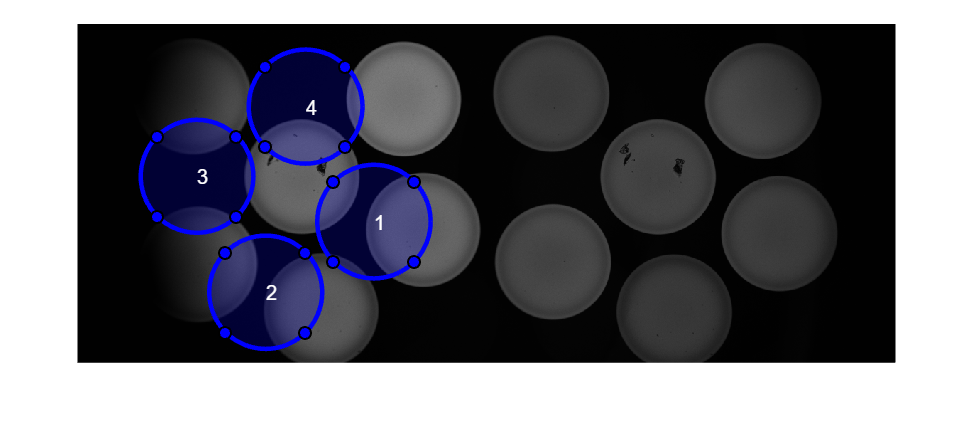

snpshot = getsnapshot(v);
num_rois = size(translated_coords, 1);
figure
imshow(snpshot);
hold on
for roi_n=1:num_rois
    circ(roi_n) = drawcircle('Center',[translated_coords(roi_n,1), translated_coords(roi_n, 2)],'Radius', translated_coords(roi_n,3), 'Color', 'blue');
    text(translated_coords(roi_n,1), translated_coords(roi_n, 2),sprintf('%d', roi_n), 'Color', 'white');
end

## 3. Check laser intensity and location,ids(1,1

Change the analog voltage applied to the laser at each fiber to get them to desired mW.

**Do not increase the digital input voltage!**

**Do not go above 5 V of analog input voltage!!!**

The laser stim input is: **[analog, digital, galvo_x, galvo_y]**, all with units of V.

IF LASER NOT IN CENTER OF FIBER, **RUN CELL 5**

% Test different voltages of fibers
% i = which fiber, goes from 1-12
i = 4; 
anlg_V = 2 % V

anlg_V = 2

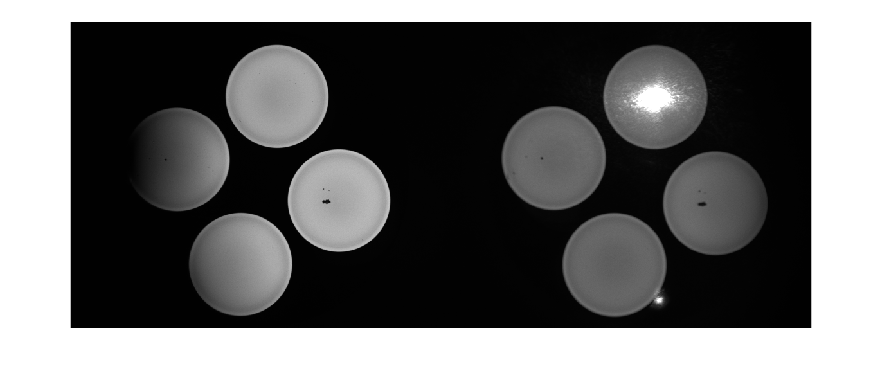

write(dq, [anlg_V, 1, lsr.galvo_grid(i,2), lsr.galvo_grid(i,3)]);

% Plot snapshot, make sure laser in center
figure;
snpshot = getsnapshot(v);
imshow(snpshot);

% write(dq, [0, 0, 0, 0]);

% Record desired voltages for each fiber here!
format long

intensity_mat = [ % these are for 1.6 mW
    1, 2]; 

% intensity_mat = [ % these are for 1.6 mW
%     1, 0.152; % VMH
%     2, 0.113; % AH
%     3, 0.115; % PFC
%     4, 0.115; % PMv
%     5, 0.16; % MeA
%     6, 0.125; % LHb
%     7, 0.115; % PAG
%     8, 0.139; % PA
%     9, 0.16; % NAc
%     10, 0.115; % vLS
%     11, 0.115; % MPOA
%     12, 0.125]; % BNST

% Save laser intensity values and turn laser off
write(dq, [0 0 0 0]);
save(sprintf('lsr_ints_%s.mat', datetime('now','Format','MMddyy')), 'intensity_mat')

## 4. Calibrate Fiber Locations for Laser Stimulation

**Note: You do not have to run this every time! Only run if fibers are off in cell 2**

The automatic calibration GUI will detect fibers and calculate where to send stimulation automatically.

Will save file to 'TranslatedCoords_mmddyy.mat'

Execute the following BEFORE attaching patchcord to mouse headplate.

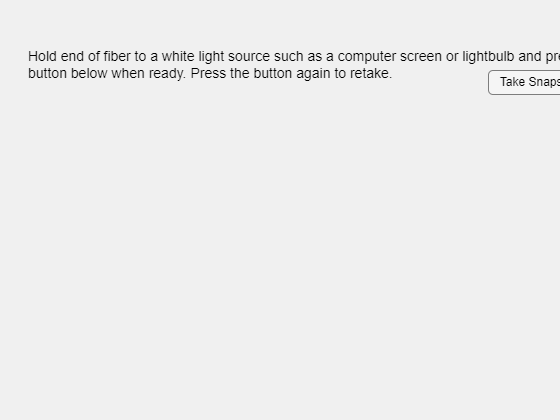

% Call automatic calibration GUI
calibrationGUIAuto;

**4b. Run to update vars with new calibration**

% Load new translated coords
load(sprintf('TranslatedCoords_%s.mat', datetime('now','Format','MMddyy')), 'translated_coords');
load(sprintf('mids_%s.mat', datetime('now','Format','MMddyy')), 'mids');

% Upload translated coords to lsr
lsr.grid = [[1:size(translated_coords, 1)].' translated_coords]; % added indices in first column to keep track of permutations later
lsr.mids = mids;

## 5. Run Auto Galvo Voltage Calibration - last calibration 2/09/26

**Note: You do not have to run this every time!!! Only run if a) the laser hardware (mirrors, laser, or any of the connecting wires) have shifted somehow, or b) laser stim location is off center in cell 3.**

Run a scipt that finds pixel-galvo voltage pairs and saves them to a 'calmtx_mmddyy.mat' file

clear v dq src
galvoCalAuto;



% Load new calibration file you just made
load(sprintf('cal_mtx_%s.mat', datetime('now','Format','MMddyy')));

% Reconnect to cam and laser
v = videoinput("hamamatsu", 1, "MONO16_BIN2x2_1152x1152_Fast");
v.ROIPosition = [0 160 576 238]*2;

src = getselectedsource(v);
src.OutputTriggerKindOpt3 = "exposure";
src.OutputTriggerPolarityOpt3 = "positive";
src.ExposureTime = 0.0125;


% Laser
dq = daq("ni");
dq.Rate = 2000; % scans/sec. Not important here yet
addoutput(dq, "Dev1", "ao0", "Voltage"); % output channel 1, corresponding to laser analog input
addoutput(dq, "Dev1", "port0/line7", "Digital"); % digital output channel USER1, corresponding to laser digital input
addoutput(dq, "Dev1", "ao2", "Voltage"); % output channel 3, corresponding to galvo X input
addoutput(dq, "Dev1", "ao3", "Voltage"); % output channel 4, corresponding to galvo Y input

## 5. Now Attach Patchcord to Mouse

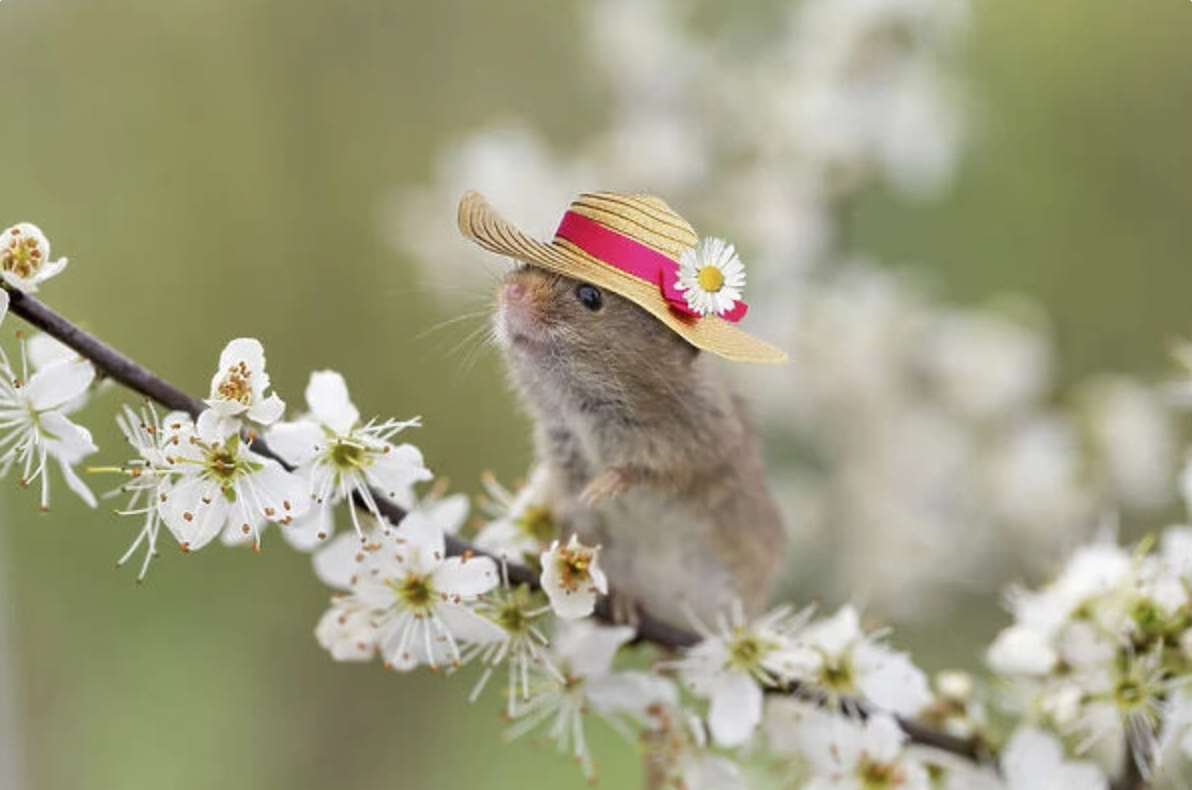

## 6. Pull up Experimental GUI to Run Experiment!

This GUI allows you to set parameters and run a stim-record experiment.

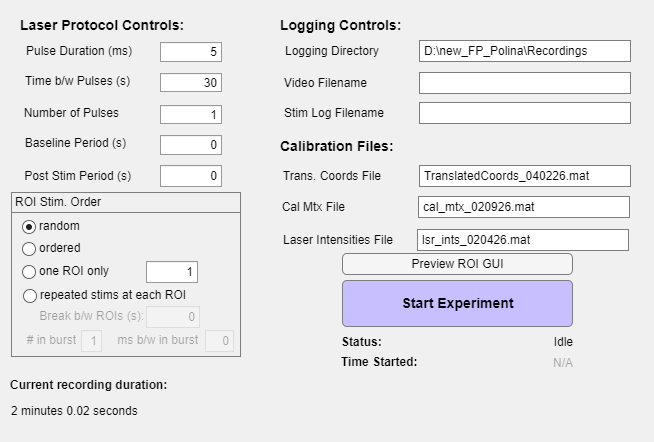

% Turn off connection to camera and laser first
clear v dq src

% Run experimental GUI:
ExperimentalGUI_TTLtrig_exported;

## **7. Turn Everything Off**

- **Check that LEDs **are set to** "Trig" **(middle) and **no light is coming out of the patchcord**

## Archives: MANUAL Galvo Voltage Calibration

**Laser location not detected automatically, must click with mouse**

% Run galvo calibration script to get calibration matrix
galvoCal;

% Load new calibration file you just made
load(sprintf('cal_mtx_%s.mat', datetime('now','Format','MMddyy')));

% Don't change anything below here

% Find function to get galvo voltages from desired pixel location
% This assumes a linear function, can change if non-linear
px = polyfit(all_points(:,3), all_points(:,1),1);
slopex = px(1,1);
intx = px(1,2);

py = polyfit(all_points(:,4), all_points(:,2),1);
slopey = py(1,1);
inty = py(1,2);

% Save to lsr
lsr.slopex = slopex;
lsr.slopey = slopey;
lsr.intx = intx;
lsr.inty = inty;

xgrid = [-3, -2, -1, 0, 1, 2, 3];

scatter(all_points(:,3), all_points(:,1), 'blue');
hold on
scatter(all_points(:,4), all_points(:,2), 'red');
plot(xgrid, xgrid*slopex + intx, 'blue')
plot(xgrid, xgrid*slopey + inty, 'red')

% Upload coords to lsr
lsr.grid = [[1:size(translated_coords, 1)].' translated_coords]; % added indices in first column to keep track of permutations later

% Get values by which to translate pixels coords to to right (red) image
% (from calibration GUI)


% Convert all coordinates to galvo voltages
galvo_coords = [];
for i = 1:size(lsr.grid,1)
    % Get desired pixel location
    pix_y = lsr.grid(i, 2) + mids(1,1);
    pix_x = lsr.grid(i, 3) + mids(1,2);

    % Convert to voltage
    gVx = (pix_y - lsr.intx)/lsr.slopex;
    gVy = (pix_x - lsr.inty)/lsr.slopey;

    % Save in matrix
    galvo_coords = [galvo_coords; gVx gVy];
end

% Upload galvo voltages to lsr
lsr.galvo_grid = [[1:size(galvo_coords, 1)].' galvo_coords]; % added indices in first column to keep track of permutations later